clc; 
clear all; close all;
start=1;
x0 = [start;0]; % x0 is the intial state of the system

tspan=[0; 10]; % simulation time
[t,x] = ode45(@sys_dynamics,tspan,x0);
n=size(t,1);
line0=zeros(n,1);
SettlingTime=0;
for i=1:n
    if abs(x(i,1))>start*0.05
        SettlingTime=t(i);
    end
end
SettlingTime

SettlingTime = 0.7353

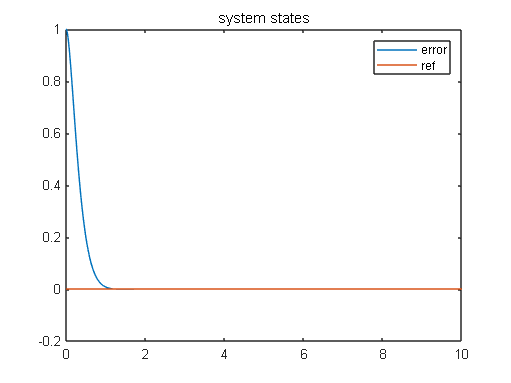

% overshoot=abs(overshoot/start*100)
 % plot the simulation data
figure; plot(t,x(:,1),t,line0); legend('error','ref'); title('system states');

function dx=sys_dynamics(t,x)
kp=30;
dx=zeros(2,1);
dx(1)=x(2);
dx(2)=-10*x(2)-kp*x(1);
end